# Pdf and Cdf of Gaussian RV

Note: this script reproduces the figures of the Gaussian RV in Section 2.2.2 of **Statistics for Chemical Engineers**: pdfs and cdfs for different parameters, realizations of N(0,1), and its critical values. Victor Z UW-Madison, 2020 compare gaussians RVs

clc; clear all; close all hidden;

## Parameters

values for mu and sigma

mu=[0,0,1];
sigma=[sqrt(1/5),sqrt(1),sqrt(1/10)];
w=[0.5,1.5,2.5];
x=linspace(-5,5,1000);

## Realizations

generate realizations

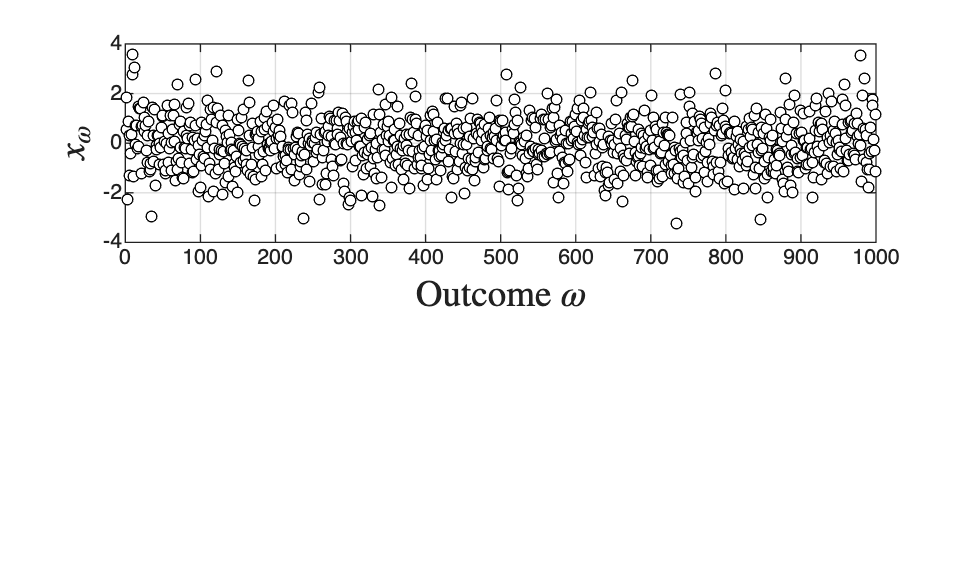

S=1000;
rng(0);
X = normrnd(0,1,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on

## Plots

visualize pdf and cdf

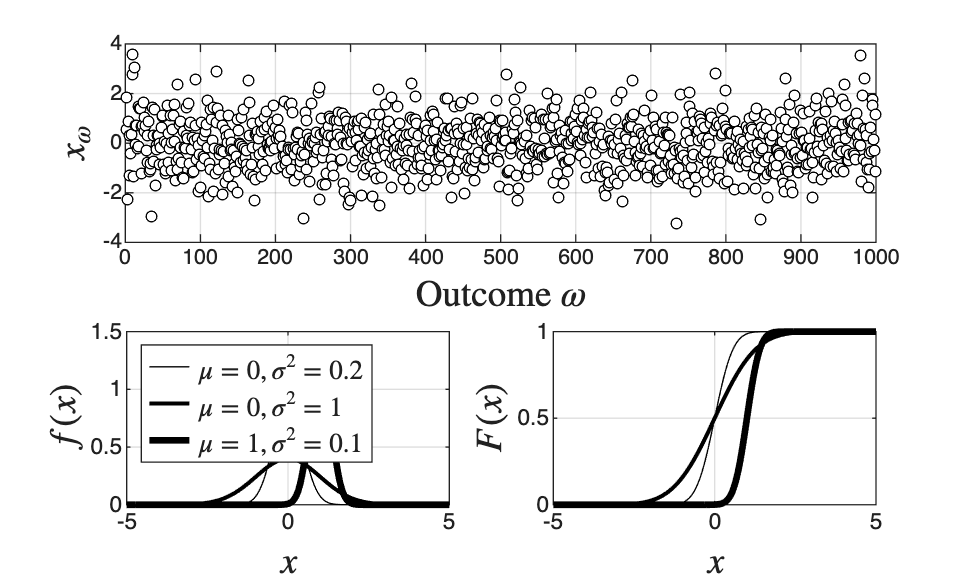

figure(1)
subplot(2,2,3)
for k=1:length(mu)
plot(x,normpdf(x,mu(k),sigma(k)),'black-','LineWidth',w(k))
hold on
end
grid on
lgd=legend('$\mu=0,\sigma^2=0.2$','$\mu=0,\sigma^2=1$',...
'$\mu=1,\sigma^2=0.1$','Interpreter','latex','location','northwest');
lgd.FontSize = 10;
lgd.ItemTokenSize = [15,9];
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')

subplot(2,2,4)
for k=1:length(mu)
plot(x,normcdf(x,mu(k),sigma(k)),'black-','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_comparegaussians.eps

## Critical values of N(0,1)

compute critical values for standard normal

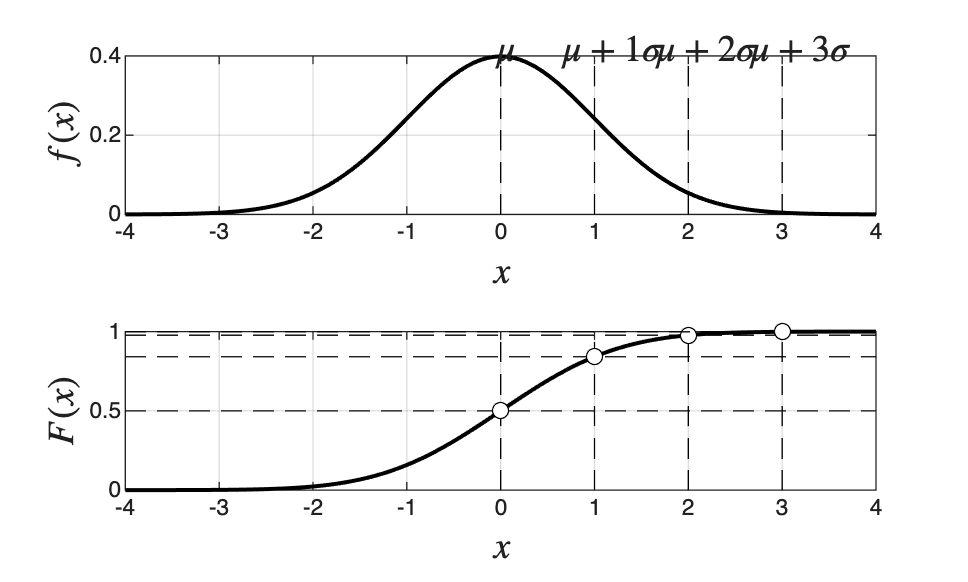

figure(2)
mu=0; sig=1;
x=linspace(mu-4*sig,mu+4*sig);
n=length(x);
subplot(2,1,1)
plot(x,normpdf(x,mu,sig),'black','LineWidth',1.5)
grid on
hold on
for k=0:3
q=mu+k*sig;
plot(q*ones(n,1),linspace(0,0.4),'black--')
hold on
end
text(-0.1,0.42,'$\mu$','Interpreter','latex','FontSize',14)
text(0.6,0.42,'$\mu+1 \sigma$','Interpreter','latex','FontSize',14)
text(1.6,0.42,'$\mu+2\sigma$','Interpreter','latex','FontSize',14)
text(2.6,0.42,'$\mu+3\sigma$','Interpreter','latex','FontSize',14)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
subplot(2,1,2)
plot(x,normcdf(x,mu,sig),'black','LineWidth',1.5)
grid on
hold on
for k=0:3
q=mu+k*sig;
plot(x,normcdf(q,mu,sig)*ones(n,1),'black--')
hold on
plot(q*ones(n,1),linspace(0,1),'black--')
hold on
scatter(q,normcdf(q,mu,sig),'MarkerFaceColor','w','MarkerEdgeColor','black')
end
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)

print -depsc ch2_gausslevels.eps

## Note

About 68%, 95%, and 99.7% of the outcomes of a Gaussian lie within 1, 2, and 3 standard deviations of the mean.